# MATLAB Functions

## Scope

- When writing and using functions, one must always be aware of **what information is visible to what function**

- Scope refers to the extent to which a variable is visible - can be referenced and/or altered

- *Local *– variable is only visible to the function in which it is defined

- *Global* – visible to all functions within a program

- *Persistent* – visible to all functions, but can only be altered by original function (rarely used)

## File Functions

- Called like any other *built-in *functions

- Function is defined in one *.m* file

- File must be name *functname.m *to be callable in MATLAB

- There *can* be multiple* <inputs> *and multiple* <outputs>* 

help fsatellite

  fsatellite is the functional form of the satellite script. It takes the
  orbital period of a satellite T and the units of time (optional). Units
  of time can include "hr" for hours (default), "min" for minutes, "s" for
  seconds, and "dy" for days. The function returns the altitude in km and
  velocity in km/s



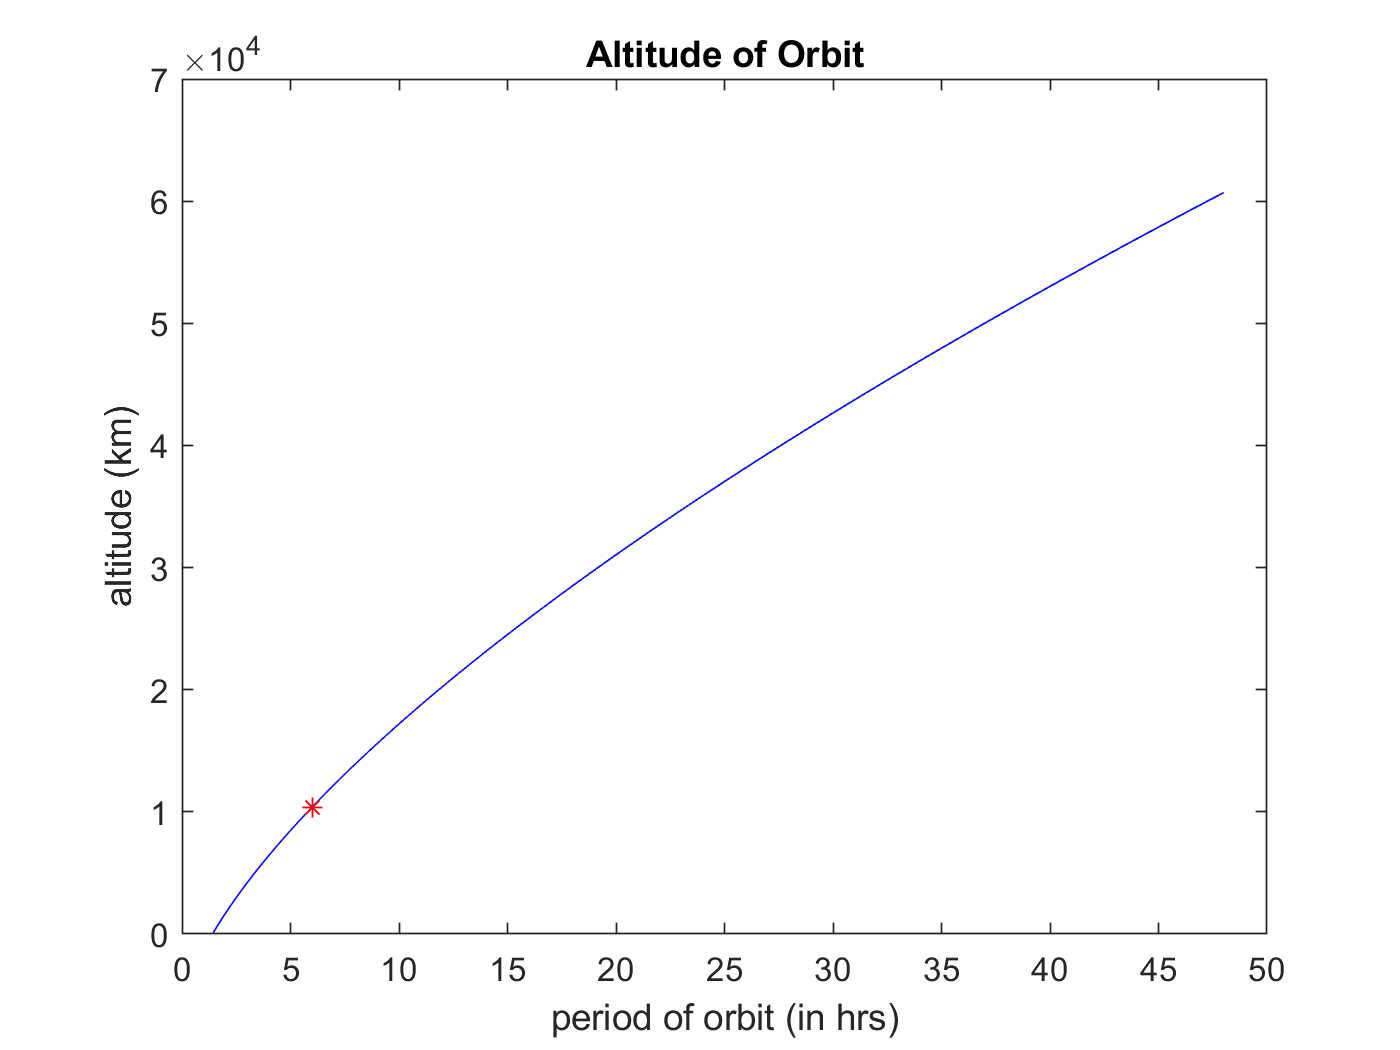

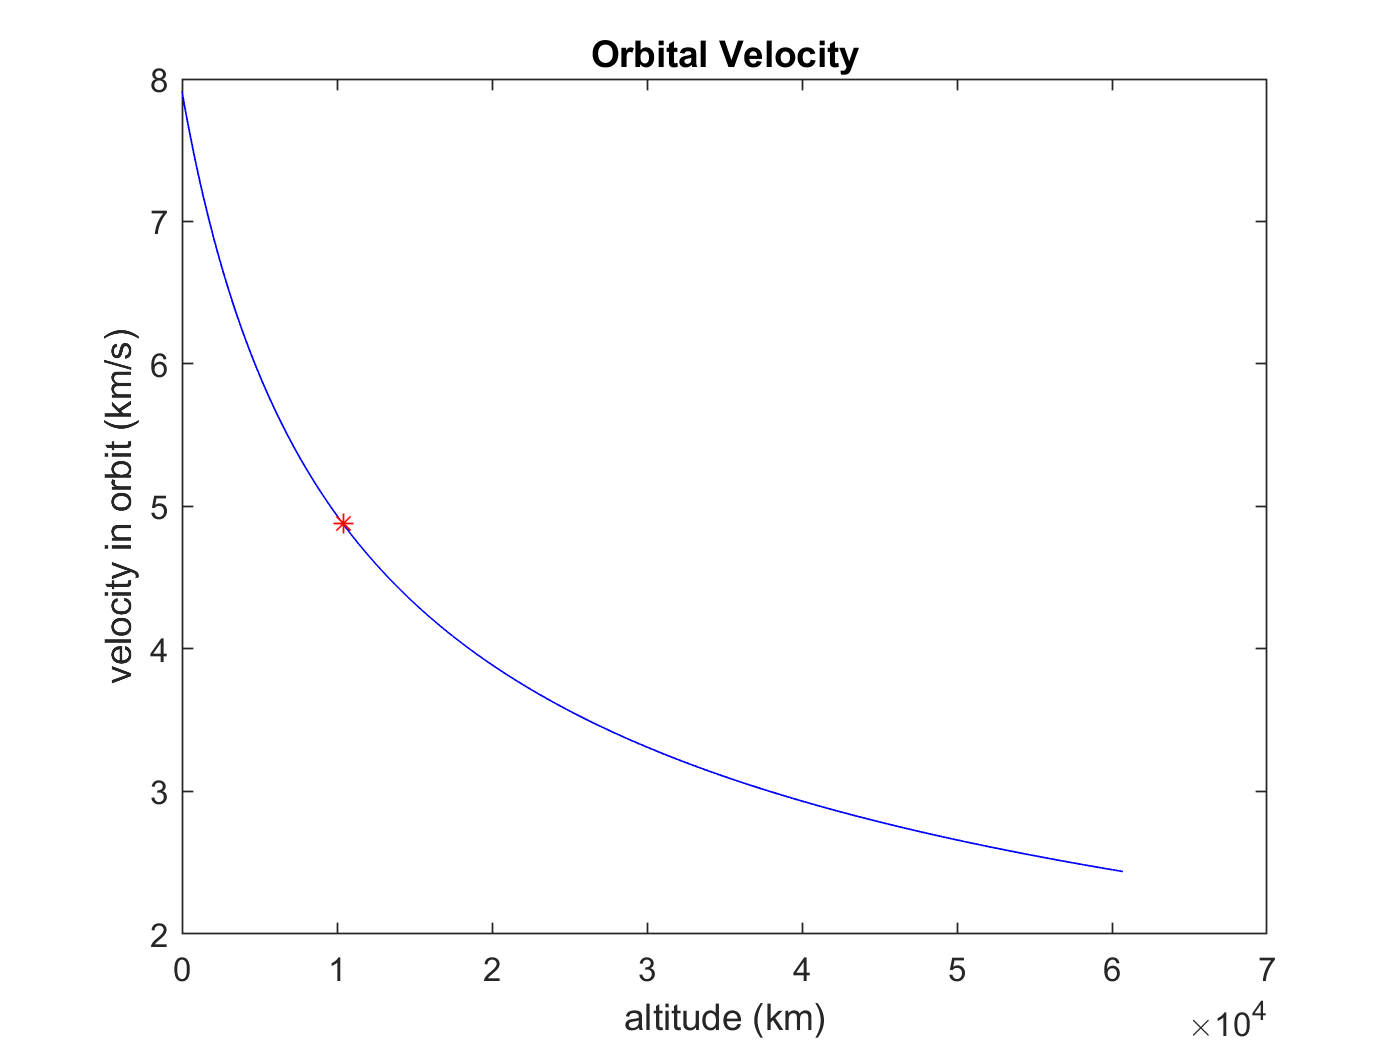

ans =      1.039611183949708e+04

fsatellite(6, "hr")

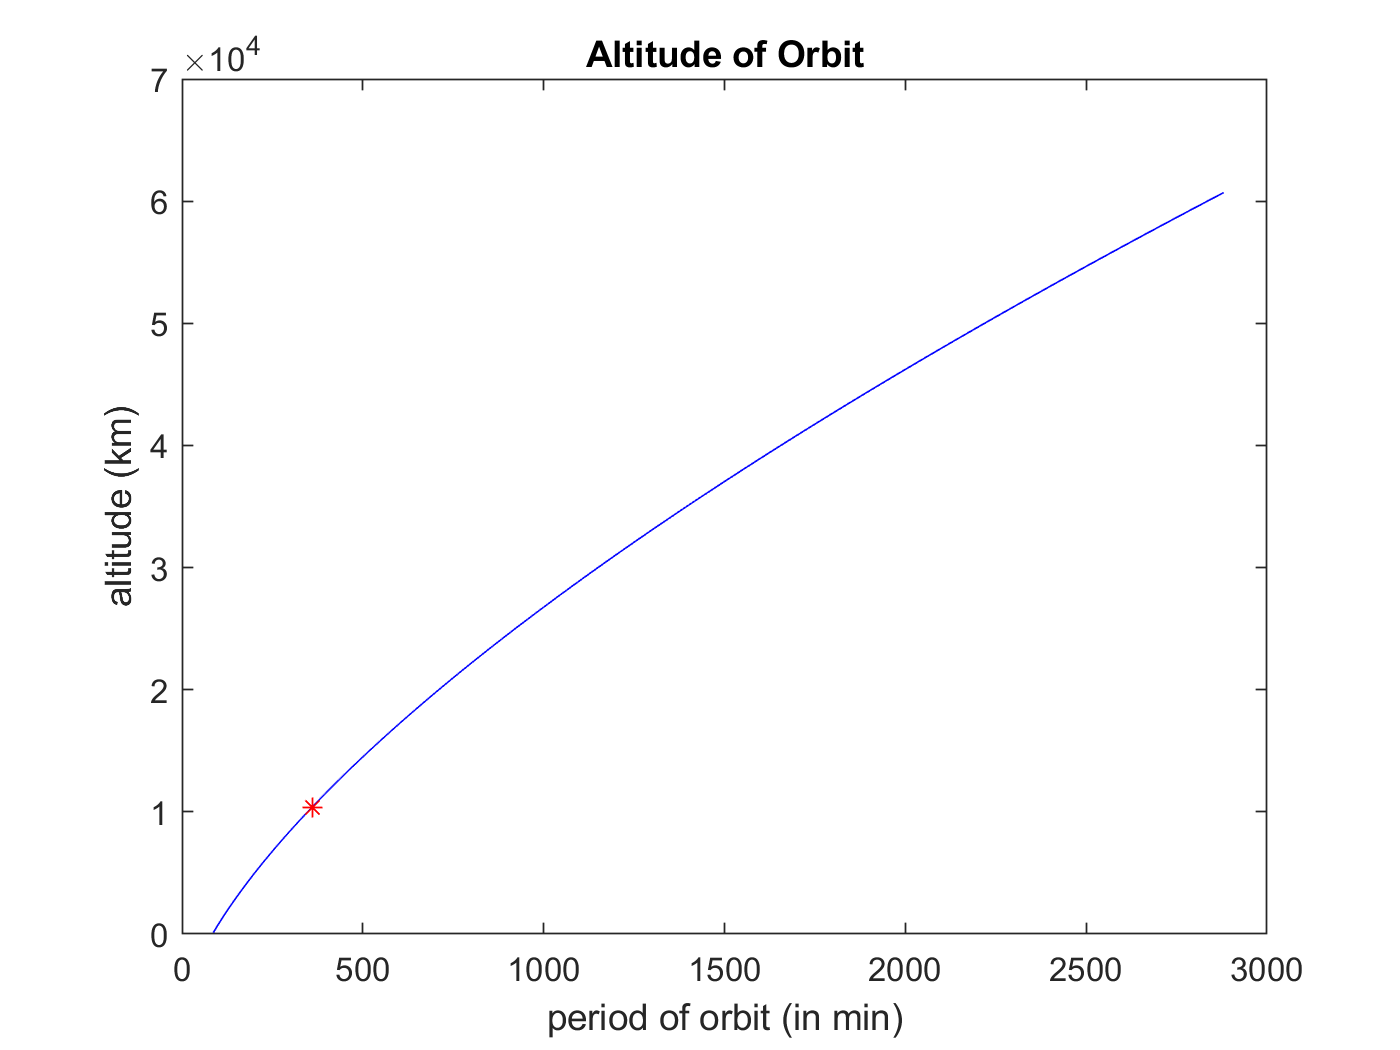

h =      1.039611183949708e+04

v =    4.877355127489123

[h,v] = fsatellite(360, "min")

## Local Functions

MATLAB allows for multiple function definitions in a file 

the first function defined is the “main” function (callable from MATLAB command line)

Any other function defined after the “main” function is only visible to the functions in the same file AND cannot be called from the command line

Can call *help* on local functions by using a '*>' *character

*Note: Local functions take precedent over any externally defined function (you may “overload” function names using local functions)*

help fsatellite>mtokm

  Converts input from meters to kilometers



## Nested Functions

**Nested functions are any functions defined inside a “parent” function**

Nested functions can access and change variables contained in the parent functions

 (this is a blessing and a curse)

type fsatellite.m


function [h,v] = fsatellite(T,unit)
% FSATELLITE is the functional form of the satellite script. It takes the
% orbital period of a satellite T and the units of time (optional). Units
% of time can include "hr" for hours (default), "min" for minutes, "s" for
% seconds, and "dy" for days. The function returns the altitude in km and
% velocity in km/s
 
if nargin==1 % nargin stores the number of arguments put in with the function
    unit= "hr";
elseif nargin ==0 
    error("Invalid input")    
end
% Defining constants
mts = 60;
hts= 3600;
dts = 86400;
G = 6.67*10^(-11);
M = 5.98*10^(24);
R = 6.371*10^(6);
% Calculations using anonymous functions!!
% Is this overkill? Maybe
V = @(r) sqrt(G*M./r);
H = @(t) (G*M*t.^2./(4*pi.^2)).^(1/3) - R;
% Checks the unit input
switch unit
    case "sec"
        t=T;
        tconvert = 1;
        lab = "sec";
    case "min"
        t= mts*T;
        tconvert = mts;
        lab = "min";
    case "hr" 
        t = hts*T; 
        tconvert = hts;
        

## Anonymous Functions

- An anonymous function is **not** stored in a file, but associated with a *function handle*

- Can only contain a **single** executable statement

- Will become invaluable in ordinary differential equations

a = 1.3;
b = .2;
c = 30;
parabola = @(x) a*x.^2 + b*x + c;
y = parabola(1)

y =          31.50

a=10;
parabola(1)

ans =          31.50

parabola = @(a,b,c,x) a*x.^2 + b*x + c;
parabola(10,10,10,1)

ans =          30.00

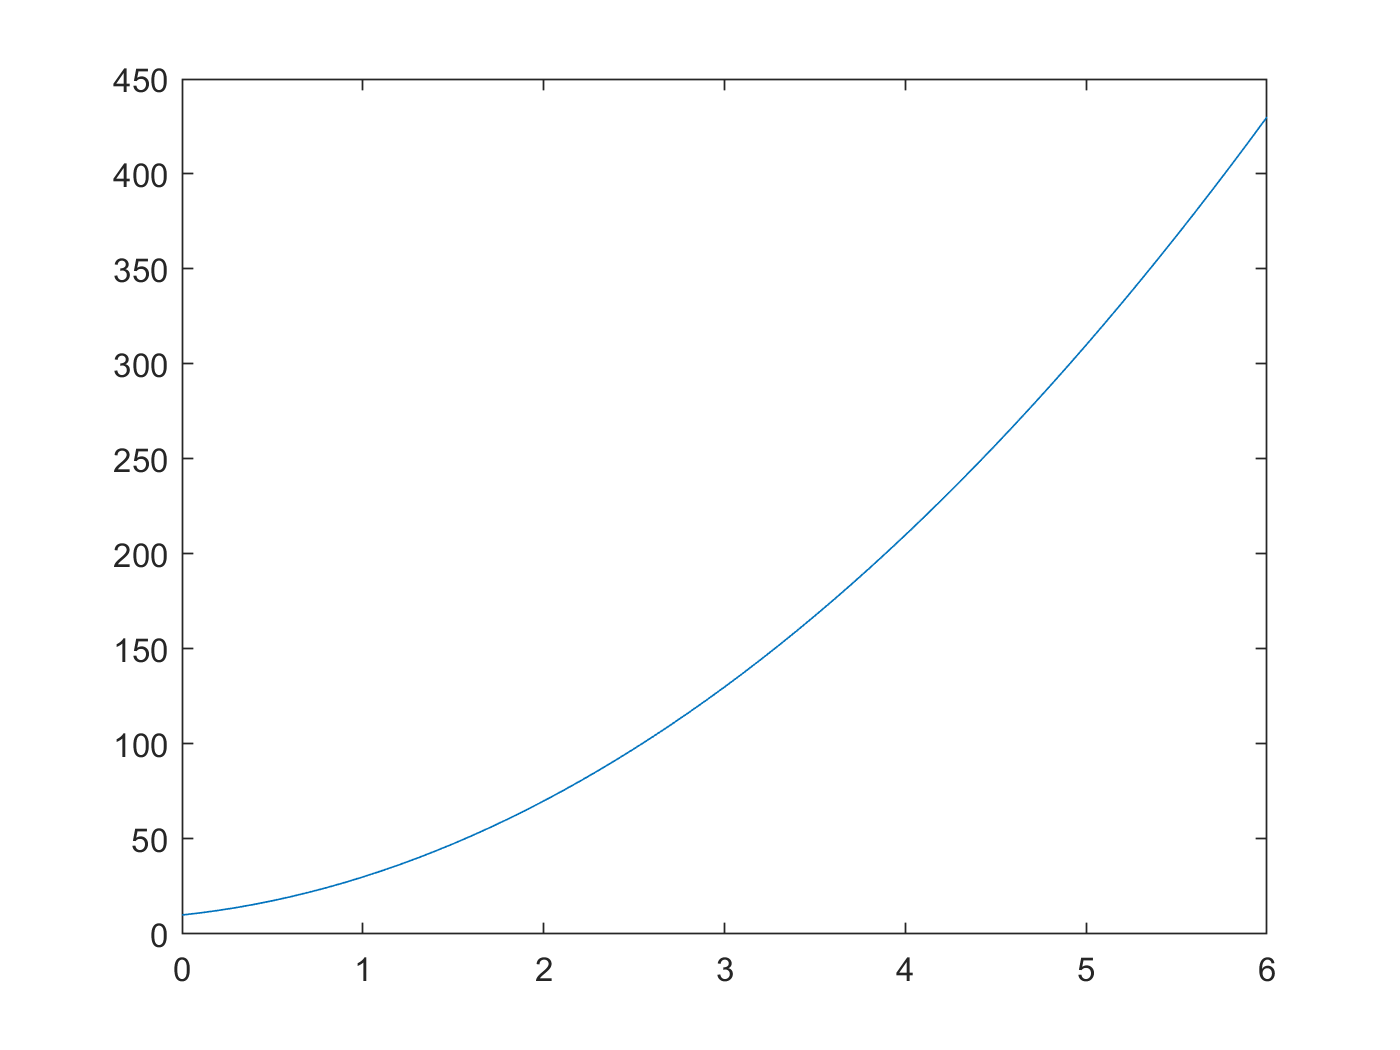

x=0:0.1:6;
plot(x,parabola(10,10,10,x))

## Order of Precedence

**When your functions have the same name as other functions/variables, MATLAB executes functions in this order**

1. Variables

2. Nested Functions within current function

3. Local Functions within current file

4.Private Functions/Object Functions/Class Constructors

5. Functions within current folder

6. Functions within other folders on MATLAB’s path